## Set up

clc
clear
clf
rng(16);

Preprocessing

SmarketD = readtable("Data\SmarketShuffle.csv");
SmarketD.Direction = categorical(SmarketD.Direction);
summary(SmarketD);

Variables:

    Var1: 1250×1 double

        Values:

            Min            1  
            Median     625.5  
            Max         1250  

    Year: 1250×1 double

        Values:

            Min         2001  
            Median      2003  
            Max         2005  

    Lag4: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag3: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag1: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag2: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag5: 1250×1 double

        Values:

           

Smarket = normalize(SmarketD(:,3:end-1));
Smarket.Direction = SmarketD.Direction;

% corrplot(Smarket(:,1:end-1));

## LDA

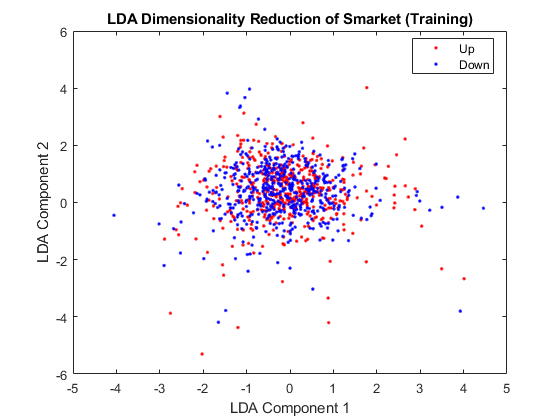

train = (SmarketD.Year < 2005);
Smarket2005 = Smarket(~train,:);
Direction2005 = SmarketD.Direction(~train,:);
ldafit = fitcdiscr(Smarket(train, 1:end-2), Smarket(train, end));
Direction = SmarketD.Direction;
num_components = 2; % Number of components in the reduced space
[eigenvectors, eigenvalues] = eig(ldafit.BetweenSigma, ldafit.Sigma);
lambda = diag(eigenvalues);
[lambda, sorted_indices] = sort(lambda, 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

Smarket_reduced = table2array(Smarket(:,1:end-2)) * projection_matrix;
Smarket2005_reduced = Smarket_reduced(~train,:);

lda_reduced = fitcdiscr(Smarket_reduced(train, :), Direction(train));

gscatter(Smarket_reduced(train, 1), Smarket_reduced(train, 2), Direction(train), 'rb');
title('LDA Dimensionality Reduction of Smarket (Training)');
xlabel('LDA Component 1');
ylabel('LDA Component 2');
legend('Up', 'Down', 'Location', 'best');


% [L, W] = meshgrid(linspace(-5, 5, 500), linspace(-5,5,100)); ...
% L = L(:);
% W = W(:);
% pred = lda_reduced.predict([L W]);
% hold on;
% h = gscatter(L, W, pred, 'rb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
% hold off; 

y_pred = predict(lda_reduced, Smarket2005_reduced);
C = confusionmat(Direction2005, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    77    34
    97    44



#### Prior probabilities

array2table(ldafit.Prior, 'VariableNames', cellstr(ldafit.ClassNames))

ans = 1×2 table
     Down        Up   
    _______    _______

    0.49198    0.50802


Group means

% array2table(ldafit.Mu, 'VariableNames',cellstr(ldafit.ClassNames))

Predictions

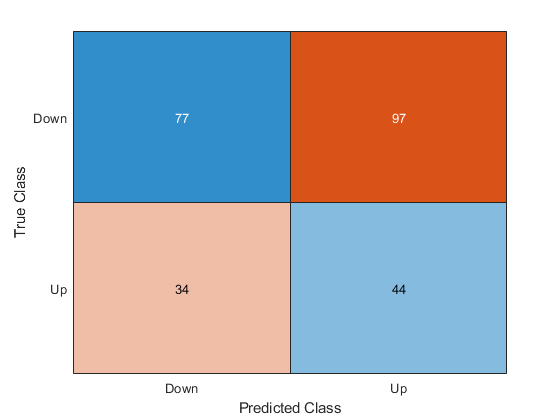

[ldaPredClass, ldaPredPosterior] = predict(lda_reduced,Smarket2005_reduced);
confusionchart(ldaPredClass, Direction2005)

mean(ldaPredClass == Direction2005)

ans = 0.4802

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 174

sum(ldaPredPosterior(:,1) < 0.5)

ans = 78

ldaPredPosterior(1:20,1).'

ans =     0.4718    0.4844    0.4774    0.4862    0.5016    0.4989    0.4972    0.4904    0.4960    0.4894    0.4899    0.5187    0.4947    0.4764    0.4832    0.4875    0.5017    0.5117    0.5039    0.4948


ldaPredClass(1:20,1).'

ans = 1×20 categorical array
     Up      Up      Up      Up      Down      Up      Up      Up      Up      Up      Up      Down      Up      Up      Up      Up      Down      Down      Down      Up 



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 0